clc;
clear;
A = 10;
w = 5*pi/10;
theta = 0;
N = 91;
n = 0:N-1;

x = A*cos(w*n + theta);

b = 1/6;
y1 = zeros(size(x));
y2 = zeros(size(x));
for i = 1:N
    switch (i)
        case 1
            y1(i) = b*x(i);
            y2(i) = b*x(i);
        case 2
            y1(i) = b*x(i) + b*x(i-1);
            y2(i) = b*x(i) - b*x(i-1);
        case 3
            y1(i) = b*x(i) + b*x(i-1) + b*x(i-2);
            y2(i) = b*x(i) - b*x(i-1) + b*x(i-2);
        case 4
            y1(i) = b*x(i) + b*x(i-1) + b*x(i-2) + b*x(i-3);
            y2(i) = b*x(i) - b*x(i-1) + b*x(i-2) - b*x(i-3);
        case 5
            y1(i) = b*x(i) + b*x(i-1) + b*x(i-2) + b*x(i-3) + b*x(i-4);
            y2(i) = b*x(i) - b*x(i-1) + b*x(i-2) - b*x(i-3) + b*x(i-4);
        otherwise
            y1(i) = b*x(i) + b*x(i-1) + b*x(i-2) + b*x(i-3) + b*x(i-4) + b*x(i-5);
            y2(i) = b*x(i) - b*x(i-1) + b*x(i-2) - b*x(i-3) + b*x(i-4) - b*x(i-5);
    end
end

figure, hold on, grid on
plot(n, x)
stem(n, x)
xlabel("n (muestras)")
ylabel("x(n)")
title("Input signal Acos(wn + \theta)")

figure, hold on, grid on
plot(n, y1)
stem(n, y1)
xlabel("n (muestras)")
ylabel("y_1(n)")
title("Output signal y_1(n)")

figure, hold on, grid on
plot(n, y2)
stem(n, y2)
xlabel("n (muestras)")
ylabel("y_2(n)")
title("Output signal y_2(n)")


clc;
clear;
A = 10;
w = linspace(0.01, pi-0.01, 20);
theta = 0;
N = 91;
n = 0:N-1;

max_x = [];
max_y1 = [];
max_y2 = [];

b = 1/6;
y1 = zeros(size(n));
y2 = zeros(size(n));

for j = w
    x = A*cos(j*n + theta);
    max_x = [max_x max(x)];

    for i = 1:N
        switch (i)
            case 1
                y1(i) = b*x(i);
                y2(i) = b*x(i);
            case 2
                y1(i) = b*x(i) + b*x(i-1);
                y2(i) = b*x(i) - b*x(i-1);
            case 3
                y1(i) = b*x(i) + b*x(i-1) + b*x(i-2);
                y2(i) = b*x(i) - b*x(i-1) + b*x(i-2);
            case 4
                y1(i) = b*x(i) + b*x(i-1) + b*x(i-2) + b*x(i-3);
                y2(i) = b*x(i) - b*x(i-1) + b*x(i-2) - b*x(i-3);
            case 5
                y1(i) = b*x(i) + b*x(i-1) + b*x(i-2) + b*x(i-3) + b*x(i-4);
                y2(i) = b*x(i) - b*x(i-1) + b*x(i-2) - b*x(i-3) + b*x(i-4);
            otherwise
                y1(i) = b*x(i) + b*x(i-1) + b*x(i-2) + b*x(i-3) + b*x(i-4) + b*x(i-5);
                y2(i) = b*x(i) - b*x(i-1) + b*x(i-2) - b*x(i-3) + b*x(i-4) - b*x(i-5);
        end
    end
    max_y1 = [max_y1 max(y1)];
    max_y2 = [max_y2 max(y2)];
end

figure, hold on, grid on
stem(w, max_x)
xlabel("w")
ylabel("Amp Input")
title("Max Input Amplitud (x)")

figure, hold on, grid on
stem(w, max_y1)
xlabel("w")
ylabel("Amp Output")
title("Max Output Amplitud (y_1)")

figure, hold on, grid on
stem(w, max_y2)
xlabel("w")
ylabel("Amp Output")
title("Max Output Amplitud (y_2)")


clc;
clear;
A = 10;
w = 5*pi/10;
theta = 0;
N = 91;
n = 0:N-1;

x = A*cos(w*n + theta);

a = 0.6;
b = 0.4;
z1 = zeros(size(x));
z2 = zeros(size(x));
for i = 1:N
    switch (i)
        case 1
            z1(i) = b*x(i);
            z2(i) = b*x(i);
        otherwise
            z1(i) = b*x(i) + a*z1(i-1);
            z2(i) = b*x(i) - a*z2(i-1);
    end
end

figure, hold on, grid on
plot(n, x)
stem(n, x)
xlabel("n (muestras)")
ylabel("x(n)")
title("Input signal Acos(wn + \theta)")

figure, hold on, grid on
plot(n, z1)
stem(n, z1)
xlabel("n (muestras)")
ylabel("y_1(n)")
title("Output signal z_1(n)")

figure, hold on, grid on
plot(n, z2)
stem(n, z2)
xlabel("n (muestras)")
ylabel("y_2(n)")
title("Output signal z_2(n)")


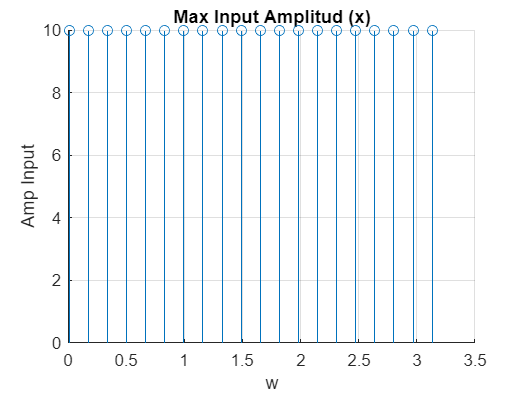

clc;
clear;
A = 10;
w = linspace(0.01, pi-0.01, 20);
theta = 0;
N = 91;
n = 0:N-1;

max_x = [];
max_z1 = [];
max_z2 = [];

a = 0.6;
b = 0.4;
z1 = zeros(size(n));
z2 = zeros(size(n));

for j = w
    x = A*cos(j*n + theta);
    max_x = [max_x max(x)];

    for i = 1:N
        switch (i)
            case 1
                z1(i) = b*x(i);
                z2(i) = b*x(i);
            otherwise
                z1(i) = b*x(i) + a*z1(i-1);
                z2(i) = b*x(i) - a*z2(i-1);
        end
    end
    max_z1 = [max_z1 max(z1)];
    max_z2 = [max_z2 max(z2)];
end

figure, hold on, grid on
stem(w, max_x)
xlabel("w")
ylabel("Amp Input")
title("Max Input Amplitud (x)")

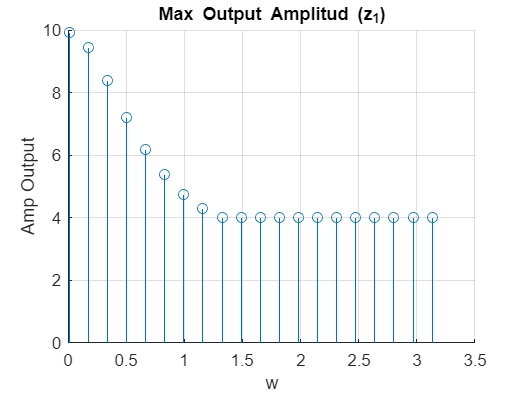


figure, hold on, grid on
stem(w, max_z1)
xlabel("w")
ylabel("Amp Output")
title("Max Output Amplitud (z_1)")

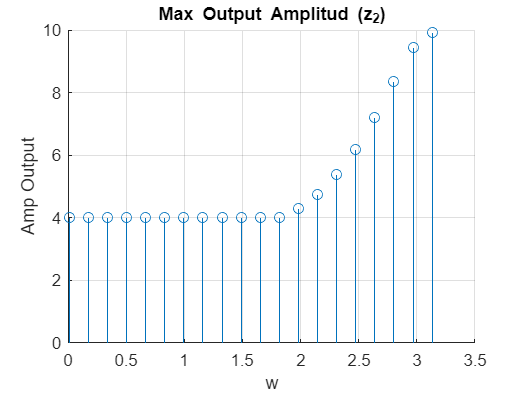


figure, hold on, grid on
stem(w, max_z2)
xlabel("w")
ylabel("Amp Output")
title("Max Output Amplitud (z_2)")